clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load
time_ms_eeg = [];

## 0.1 Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Load excel file paths for P2 and P3 ONCE per condition
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
    end

    % --- NEW: Loop through ALL subjects for this condition ---
    for s = 1:length(names_sorted)
        file_to_load = names_sorted{s}; 
        fprintf('Loading Subj %d/%d (%s) for condition: %s\n', s, length(names_sorted), file_to_load, condition);
        
        EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
        if isempty(fs), fs = EEG.srate; end
        
        if isempty(time_ms_eeg)
            time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 
        end
        
        % Extract data and store in a cell array to avoid dimension mismatch
        if ismember(condition, {'BLA', 'BLT', 'P1'})
            epoch_trials = 1:2:EEG.trials;
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials);
            
        elseif strcmp(condition, 'P2')
            epoch_trials_p2 = 1:2:EEG.trials;     
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials_p2);
            data_all_conds.P2_500{s}      = EEG.data(:, :, epoch_trials_p2_500ms);
            data_all_conds.P2_2000{s}     = EEG.data(:, :, epoch_trials_p2_2000ms);
            
        elseif strcmp(condition, 'P3')
            epoch_trials_p3 = 1:2:EEG.trials;
            data_all_conds.(condition){s}   = EEG.data(:, :, epoch_trials_p3);
            data_all_conds.P3_500{s}        = EEG.data(:, :, epoch_trials_p3_500ms);
            data_all_conds.P3_missing{s}    = EEG.data(:, :, epoch_trials_p3_missing);
        end
    end
end

Loading Subj 1/14 (binepochs filtered ICArej BLAAvgBOS10.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLAAvgBOS11.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLAAvgBOS12.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLAAvgBOS13.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLAAvgBOS15.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLAAvgBOS16.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLAAvgBOS17.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLAAvgBOS2.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLAAvgBOS3.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLAAvgBOS5.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLAAvgBOS6.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLAAvgBOS7.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLAAvgBOS8.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLAAvgBOS9.set) for condition: BLA


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej BLTAvgBOS10.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLTAvgBOS11.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLTAvgBOS12.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLTAvgBOS13.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLTAvgBOS15.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLTAvgBOS16.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLTAvgBOS17.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLTAvgBOS2.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLTAvgBOS3.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLTAvgBOS5.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLTAvgBOS6.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLTAvgBOS7.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLTAvgBOS8.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLTAvgBOS9.set) for condition: BLT


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P1AvgBOS10.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P1AvgBOS11.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P1AvgBOS12.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P1AvgBOS13.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P1AvgBOS15.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P1AvgBOS16.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P1AvgBOS17.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P1AvgBOS2.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P1AvgBOS3.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P1AvgBOS5.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P1AvgBOS6.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P1AvgBOS7.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P1AvgBOS8.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P1AvgBOS9.set) for condition: P1


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P2AvgBOS10.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P2AvgBOS11.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P2AvgBOS12.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P2AvgBOS13.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P2AvgBOS15.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P2AvgBOS16.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P2AvgBOS17.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P2AvgBOS2.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P2AvgBOS3.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P2AvgBOS5.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P2AvgBOS6.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P2AvgBOS7.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P2AvgBOS8.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P2AvgBOS9.set) for condition: P2


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P3AvgBOS10.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P3AvgBOS11.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P3AvgBOS12.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P3AvgBOS13.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P3AvgBOS15.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P3AvgBOS16.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P3AvgBOS17.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P3AvgBOS2.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P3AvgBOS3.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P3AvgBOS5.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P3AvgBOS6.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P3AvgBOS7.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P3AvgBOS8.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P3AvgBOS9.set) for condition: P3


pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1. Condition-Dependent Spatial Covariance Analysis

% Implements Document 1 rationale: Uncentered second-moment decomposition,
% split-half noise ceiling estimation, Checkpoint 1 diagnostics, and
% log-ratio profiles. 
% 1. Configuration Parameters (Document 2, §1)
cfg = struct();
cfg.num_ch        = 32;
cfg.fs            = 512;               % Sampling frequency (Hz)
cfg.tStart        = -1.000;            % Epoch start rel. to EXPECTED tactile moment (s)
cfg.win           = [0.000, 0.500];    % Analysis window (0 to 500 ms post-expected)
cfg.base          = [-1.000, -0.800];  % Pre-cue baseline window (Auditory cue is at -0.5s)
cfg.base_robust   = [-0.800, -0.600];  % Robustness check baseline window
cfg.nTrialMatch   = 30;                % Fixed trial count per condition subsample
cfg.nRep          = 50;                % Split/subsample repetitions
cfg.m             = 6;                 % Number of retained spatial directions
cfg.alpha         = 0.05;              % Covariance shrinkage parameter
cfg.seed          = 20260910;

% Condition groups
cfg.ref_cond      = 'BLT';
cfg.group_A       = {'P1', 'P2_500', 'P3_500'};        % Tactile delivered at t = 0
cfg.group_B       = {'P2_2000', 'P3_missing'};         % Stimulus omitted/delayed at t = 0
cfg.all_conds     = [{'BLT'}, cfg.group_A, cfg.group_B];

clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLT', 'Tactile (BLT)'), 'P1', 'Cued (P1)'), ...
    'P2_500', 'Unpred 500 (P2)'), 'P2_2000', 'Unpred 2000 (P2)'), ...
    'P3_500', 'Rand 500 (P3)'), 'P3_missing', 'Rand Null (P3)');


## 2. Time Axis Alignment & Window Masking

% Re-center time so t = 0 is exactly the expected tactile moment (raw 1.0s)
if max(time_ms_eeg) > 2.0
    time_s = time_ms_eeg - 1.000; % Shift: raw 1.0s becomes t = 0.0s
else
    time_s = time_ms_eeg;
end

iWin   = time_s >= cfg.win(1)  & time_s < cfg.win(2);
iBase  = time_s >= cfg.base(1) & time_s < cfg.base(2);
T_win  = nnz(iWin);
t_eval = time_s(iWin);

## 3. Helper Functions: Centered Covariance, Shrinkage & Latency

shrinkCov = @(C, a) (1 - a) * C + a * (trace(C) / size(C, 1)) * eye(size(C, 1));

covCentered = @(X, b, a) ...
    shrinkCov((( (X - b) - mean(X - b, 2) ) * ( (X - b) - mean(X - b, 2) )') / size(X, 2), a);

## 4. CHECKPOINT 1: Multi-Subject Eigenbasis Extraction & Diagnostics

% Preallocate arrays for all subjects
num_subjects = length(data_all_conds.BLT);
Xi_all_subjs = nan(cfg.num_ch, cfg.m, num_subjects);
lam_frac_all = nan(cfg.m, num_subjects);
gap_all      = nan(cfg.m - 1, num_subjects);

fprintf('\n======================================================\n');

fprintf('RUNNING CHECKPOINT 1 DIAGNOSTICS (Centered Covariance)\n');

RUNNING CHECKPOINT 1 DIAGNOSTICS (Centered Covariance)


fprintf('======================================================\n');

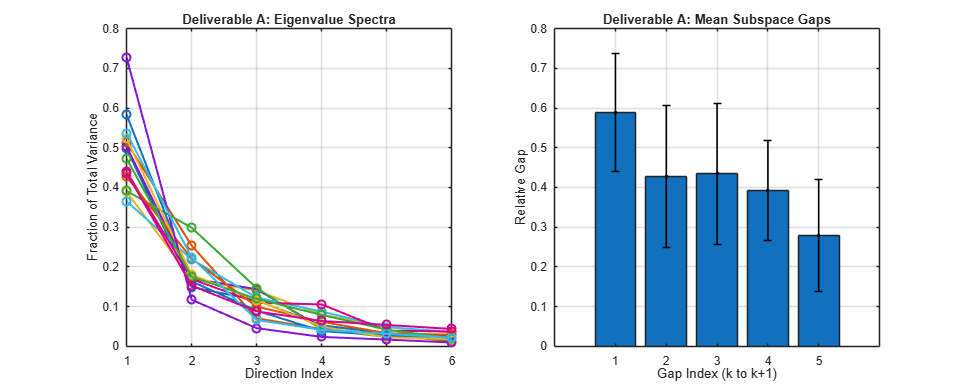


for s = 1:num_subjects
    raw_BLT = data_all_conds.BLT{s};
    n_trials = size(raw_BLT, 3);
    if n_trials < (cfg.nTrialMatch * 2)
        error('Subject %d has insufficient BLT trials (%d < 60)', s, n_trials);
    end
    
    % Use fixed seed for deterministic Checkpoint 1 baseline
    rng(cfg.seed + s);
    perm = randperm(n_trials);
    iA = perm(1:cfg.nTrialMatch);
    
    erpA = mean(raw_BLT(:, :, iA), 3, 'omitnan');
    bA   = mean(erpA(:, iBase), 2);
    
    % UPDATED: Centered covariance for eigenvector basis extraction
    C_A_cent = covCentered(erpA(:, iWin), bA, cfg.alpha);
    
    [V, D] = eig(C_A_cent, 'vector');
    [lam, ord] = sort(D, 'descend');
    V = V(:, ord);
    
    Xi_all_subjs(:, :, s) = V(:, 1:cfg.m);
    lam_frac_all(:, s)   = lam(1:cfg.m) / sum(lam);
    gap_all(:, s)        = (lam(1:cfg.m-1) - lam(2:cfg.m)) ./ lam(1:cfg.m-1);
end

% Sign-align eigenvectors to Subject 1 for Deliverable B & C
Xi_aligned = Xi_all_subjs;
for s = 2:num_subjects
    for k = 1:cfg.m
        if dot(Xi_aligned(:, k, s), Xi_aligned(:, k, 1)) < 0
            Xi_aligned(:, k, s) = -Xi_aligned(:, k, s);
        end
    end
end
Xi_bar = mean(Xi_aligned, 3);

% --- Deliverable A: Normalized Spectra & Relative Gaps ---
figA = figure('Position', [100, 100, 1000, 400], 'Name', 'Checkpoint 1 - Deliverable A');
subplot(1, 2, 1);
plot(1:cfg.m, lam_frac_all, '-o', 'LineWidth', 1.5);
grid on; xlabel('Direction Index', 'FontSize', 16); ylabel('Fraction of Total Variance', 'FontSize', 16);
title('Deliverable A: Eigenvalue Spectra', 'FontSize', 16);

subplot(1, 2, 2);
bar(mean(gap_all, 2)); hold on;
errorbar(1:cfg.m-1, mean(gap_all, 2), std(gap_all, 0, 2), 'k.', 'LineWidth', 1.2);
grid on; xlabel('Gap Index (k to k+1)', 'FontSize', 16); ylabel('Relative Gap', 'FontSize', 16);
title('Deliverable A: Mean Subspace Gaps', 'FontSize', 16);

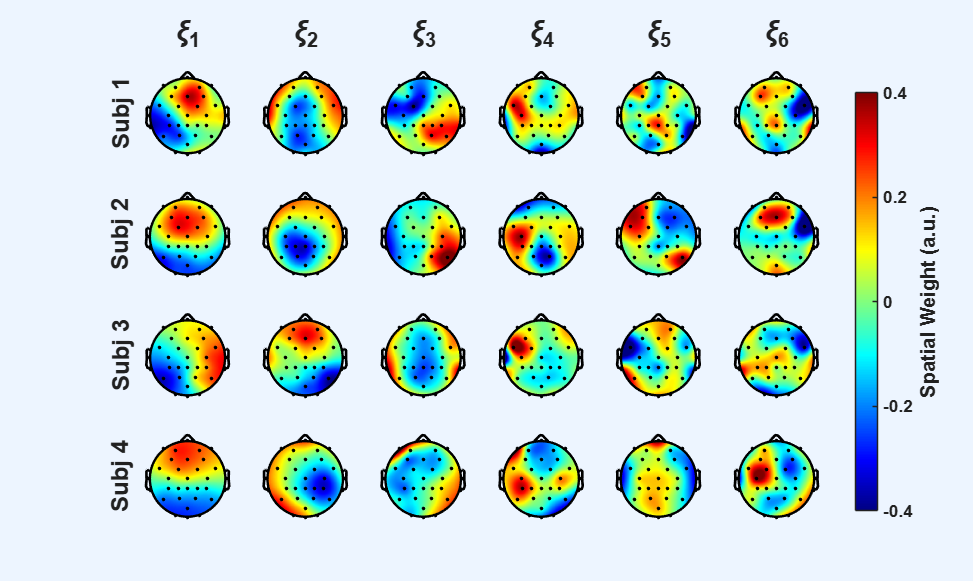


% --- Deliverable B: Topoplots of Retained Directions ---
n_rows = min(num_subjects, 4);
fig_w = 200 * cfg.m + 140; 
fig_h = 190 * n_rows + 40; % Added +40px headroom for large column headers

figure('Position', [50, 50, fig_w, fig_h], 'Name', 'Checkpoint 1 - Deliverable B');

for s = 1:n_rows
    for k = 1:cfg.m
        ax = subplot(n_rows, cfg.m, (s-1)*cfg.m + k);
        
        % Compress subplots and shift slightly down/right for label breathing room
        pos = get(ax, 'Position');
        set(ax, 'Position', [pos(1) * 0.90 + 0.03, pos(2) * 0.95, pos(3) * 0.90, pos(4) * 0.95]);
        
        topoplot(Xi_aligned(:, k, s), EEG.chanlocs, 'numcontour', 0);
        clim([-0.4 0.4]); 
        colormap('jet');
        
        % --- REPLACED title() WITH NORMALIZED text() (Immune to Auto-Shrinking) ---
        if s == 1
            text(0.5, 1.18, sprintf('\\xi_%d', k), ...
                'Units', 'normalized', ...
                'FontSize', 22, ...
                'FontWeight', 'bold', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom');
        end
        
        % Normalized Subject Labels
        if k == 1
            text(-0.28, 0.5, sprintf('Subj %d', s), ...
                'Units', 'normalized', ...
                'FontSize', 18, ...
                'FontWeight', 'bold', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'middle', ...
                'Rotation', 90);
        end
    end
end

% Global colorbar spanning the grid height
cb = colorbar('Position', [0.88, 0.12, 0.022, 0.72]); 
cb.FontSize = 13;
cb.FontWeight = 'bold';
cb.Ticks = [-0.4, -0.2, 0, 0.2, 0.4];
cb.Label.String = 'Spatial Weight (a.u.)';
cb.Label.FontSize = 15;
cb.Label.FontWeight = 'bold';

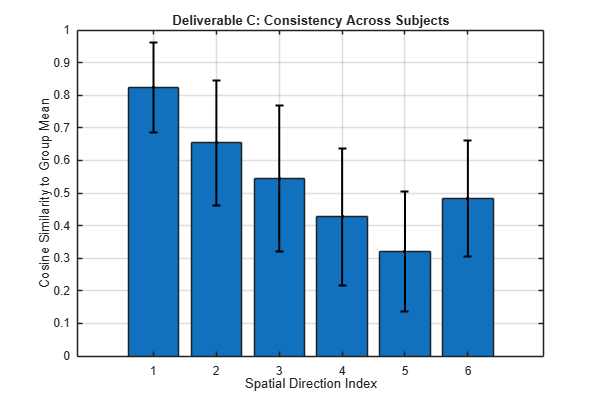


% --- Deliverable C: Cross-Subject Eigenvector Similarity ---
sim_matrix = nan(num_subjects, cfg.m);
for s = 1:num_subjects
    for k = 1:cfg.m
        sim_matrix(s, k) = abs(dot(Xi_aligned(:, k, s), Xi_bar(:, k))) / ...
            (norm(Xi_aligned(:, k, s)) * norm(Xi_bar(:, k)));
    end
end

figure('Position', [150, 150, 600, 400], 'Name', 'Checkpoint 1 - Deliverable C');
bar(mean(sim_matrix, 1)); hold on;
errorbar(1:cfg.m, mean(sim_matrix, 1), std(sim_matrix, 0, 1), 'k.', 'LineWidth', 1.5);
grid on; xlabel('Spatial Direction Index', 'FontSize', 16); ylabel('Cosine Similarity to Group Mean', 'FontSize', 16);
title('Deliverable C: Consistency Across Subjects', 'FontSize', 16); ylim([0 1]);


fprintf('Checkpoint 1 diagnostics generated. STOP and review before proceeding.\n');

Checkpoint 1 diagnostics generated. STOP and review before proceeding.


## 5. PROJECTIONS & METRICS (Gain, Geometry, Latency, Sustained/Dynamic)

target_subj = 1; % Evaluating Subject 1
Xi = Xi_aligned(:, :, target_subj);

% Metric storage across 50 splits: [Conditions x Reps]
G_splits       = nan(length(cfg.all_conds), cfg.nRep);
log_r_splits   = nan(length(cfg.all_conds), cfg.m, cfg.nRep);
lat_splits     = nan(length(cfg.all_conds), cfg.nRep);
sust_splits    = nan(length(cfg.all_conds), cfg.m, cfg.nRep);

for rep = 1:cfg.nRep
    rng(cfg.seed + rep);
    
    % 1. Split BLT into Half A (Basis) and Half B (Ceiling)
    nB = size(data_all_conds.BLT{target_subj}, 3);
    perm = randperm(nB);
    iB = perm(cfg.nTrialMatch + (1:cfg.nTrialMatch));
    
    erpB = mean(data_all_conds.BLT{target_subj}(:, :, iB), 3, 'omitnan');
    bB   = mean(erpB(:, iBase), 2);
    XB   = erpB(:, iWin) - bB;
    
    % Noise ceiling reference variance (Document 2, §4.2)
    v_ceil = sum((Xi' * XB).^2, 2) / T_win;
    V_ceil = sum(v_ceil);
    
    % Noise ceiling reference latency along xi_1
    proj_B = Xi(:, 1)' * XB;
    [~, max_idx_B] = max(abs(proj_B));
    t_lat_ceil = t_eval(max_idx_B);
    
    % 2. Project each comparison condition
    for c = 1:length(cfg.all_conds)
        cond = cfg.all_conds{c};
        if ~isfield(data_all_conds, cond), continue; end
        
        raw_cond = data_all_conds.(cond){target_subj};
        if strcmp(cond, 'BLT')
            Xk = XB; % Evaluate noise ceiling
            bk = bB;
        else
            idx_k = randperm(size(raw_cond, 3), cfg.nTrialMatch);
            erp_k = mean(raw_cond(:, :, idx_k), 3, 'omitnan');
            bk    = mean(erp_k(:, iBase), 2);
            Xk    = erp_k(:, iWin) - bk;
        end
        
        % Variance, Gain, Geometry (Document 2, §7)
        v_k = sum((Xi' * Xk).^2, 2) / T_win;
        V_k = sum(v_k);
        
        G_splits(c, rep)        = V_k / V_ceil;
        log_r_splits(c, :, rep) = log(v_k ./ v_ceil);
        
        % Latency along xi_1 (Relative to Noise Ceiling)
        proj_k = Xi(:, 1)' * Xk;
        [~, max_idx_k] = max(abs(proj_k));
        lat_splits(c, rep) = (t_eval(max_idx_k) - t_lat_ceil) * 1000; % ms shift
        
        % Sustained vs Dynamic Decomposition (Document 2, §2.4)
        xbar   = mean(Xk, 2);
        Xd     = Xk - xbar;
        v_sust = (Xi' * xbar).^2;
        v_dyn  = sum((Xi' * Xd).^2, 2) / T_win;
        sust_splits(c, :, rep) = v_sust ./ (v_sust + v_dyn + eps);
    end
end

## 6. CHECKPOINT 2: Results Display (Group A vs Group B)

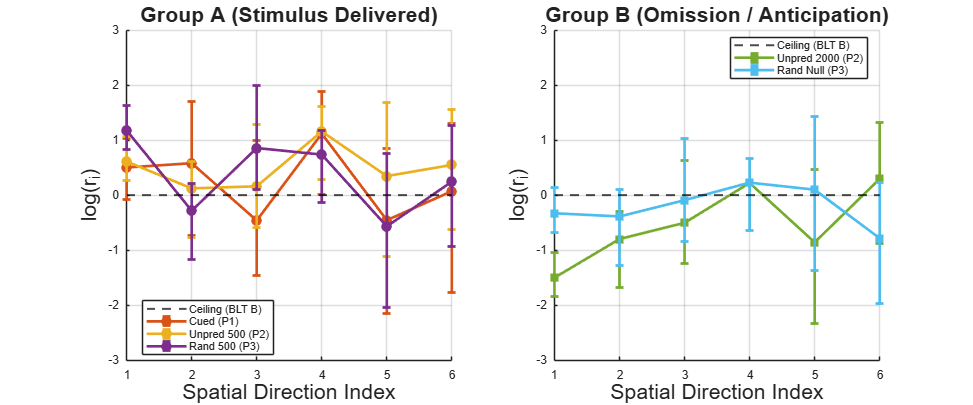

%% 6. CHECKPOINT 2: Results Display (Group A vs Group B)
mean_log_r = mean(log_r_splits, 3, 'omitnan'); % [nCond x m]
prc_log_r  = prctile(log_r_splits, [5 95], 3); % [nCond x m x 2]

% Calculate dynamic global y-limits across both groups to show full error bars
all_low  = prc_log_r(:, :, 1);
all_high = prc_log_r(:, :, 2);
y_min    = min(-1.5, floor(min(all_low(:)) * 1.15));
y_max    = max( 1.5, ceil(max(all_high(:)) * 1.15));
y_limits = [y_min, y_max]; % Automatically expands beyond [-1.5, 1.5]

figure('Position', [100, 100, 1200, 500], 'Name', 'Checkpoint 2 - Subspace Redistribution');

% -------------------------------------------------------------------------
% Group A (Stimulus Delivered at t = 0)
% -------------------------------------------------------------------------
subplot(1, 2, 1); hold on;
yline(0, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Ceiling (BLT B)');
colors_A = {[0.85 0.32 0.09], [0.92 0.69 0.12], [0.49 0.18 0.55]};

for i = 1:length(cfg.group_A)
    c_idx = find(strcmp(cfg.all_conds, cfg.group_A{i}));
    if isempty(c_idx), continue; end
    
    y_val    = mean_log_r(c_idx, :);              
    err_low  = y_val - prc_log_r(c_idx, :, 1);    
    err_high = prc_log_r(c_idx, :, 2) - y_val;    
    
    errorbar(1:cfg.m, y_val, err_low, err_high, ...
        '-o', 'Color', colors_A{i}, 'LineWidth', 2, 'MarkerFaceColor', colors_A{i}, ...
        'DisplayName', clean_name(cfg.group_A{i}));
end
grid on; xlabel('Spatial Direction Index', 'FontSize', 16); ylabel('log(r_i)', 'FontSize', 16);
title('Group A (Stimulus Delivered)', 'FontSize', 16); legend('Location', 'best'); 
ylim(y_limits);

% -------------------------------------------------------------------------
% Group B (Stimulus Omitted/Delayed at t = 0)
% -------------------------------------------------------------------------
subplot(1, 2, 2); hold on;
yline(0, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Ceiling (BLT B)');
colors_B = {[0.46 0.67 0.18], [0.30 0.74 0.93]};

for i = 1:length(cfg.group_B)
    c_idx = find(strcmp(cfg.all_conds, cfg.group_B{i}));
    if isempty(c_idx), continue; end
    
    y_val    = mean_log_r(c_idx, :);              
    err_low  = y_val - prc_log_r(c_idx, :, 1);    
    err_high = prc_log_r(c_idx, :, 2) - y_val;    
    
    errorbar(1:cfg.m, y_val, err_low, err_high, ...
        '-s', 'Color', colors_B{i}, 'LineWidth', 2, 'MarkerFaceColor', colors_B{i}, ...
        'DisplayName', clean_name(cfg.group_B{i}));
end
grid on; xlabel('Spatial Direction Index', 'FontSize', 16); ylabel('log(r_i)', 'FontSize', 16);
title('Group B (Omission / Anticipation)', 'FontSize', 16); legend('Location', 'best'); 
ylim(y_limits);

## 7. Summary Table: Gain (G), Geometry Tilt, Latency Shift, Sustained %

fprintf('\n========================================================================================\n');

fprintf('%-18s | %-10s | %-10s | %-18s | %-15s\n', ...
    'Condition', 'Gain (G)', 'log(r_1)', '\Delta Latency (\xi_1)', 'Sustained % (\xi_1)');

Condition          | Gain (G)   | log(r_1)   | \Delta Latency (\xi_1) | Sustained % (\xi_1)


fprintf('----------------------------------------------------------------------------------------\n');

----------------------------------------------------------------------------------------


for c = 1:length(cfg.all_conds)
    cond = cfg.all_conds{c};
    med_G   = median(G_splits(c, :));
    med_lr1 = median(log_r_splits(c, 1, :));
    med_lat = median(lat_splits(c, :));
    med_sus = median(sust_splits(c, 1, :)) * 100;
    
    fprintf('%-18s | %-10.3f | %-10.3f | %+7.1f ms         | %6.2f%%\n', ...
        cond, med_G, med_lr1, med_lat, med_sus);
end

BLT                | 1.000      | 0.000      |    +0.0 ms         |   6.06%
P1                 | 1.295      | 0.459      |   +93.8 ms         |  40.89%
P2_500             | 1.431      | 0.608      |   -23.5 ms         |   6.88%
P3_500             | 1.977      | 1.174      |  +134.8 ms         |  32.06%
P2_2000            | 0.446      | -1.503     |   -31.3 ms         |  15.61%
P3_missing         | 0.744      | -0.333     |    +3.9 ms         |  72.88%


fprintf('========================================================================================\n');